# SPECTER Planar Dynamics Model

clear
clc
close all

## Initial Conditions

x0 = 0;
z0 = 0;
vx0 = 0;
vz0 = 0;
theta0 = 0;
omega0 = 0;

X0 = [x0;
    z0;
    vx0;
    vz0;
    theta0;
    omega0];

## Parameters

p.m = 10;
p.g = 9.80665;
p.T = 200

p = struct with fields:
    m: 10
    g: 9.8066
    T: 200


p.l = 0.3;
p.I = 0.5;
p.delta = deg2rad(5);

## Dynamics Function Check

dX_test = SpecterDynamicsPlanar(0,X0,p)

dX_test =          0
         0
    1.7431
   10.1172
         0
   10.4587


## Simulation

tfinal = 2;

dynamics = @(t,X) SpecterDynamicsPlanar(t,X,p);
solverOptions = odeset('RelTol',1e-9,'AbsTol',1e-11);
[t,X] = ode45(dynamics,[0,tfinal],X0,solverOptions);

## State Histories

x = X(:,1);
z = X(:,2);

vx = X(:,3);
vz = X(:,4);

theta = X(:,5);
omega = X(:,6);


## Initial Verification

fprintf('\n--- PLANAR MODEL INITIAL CHECK ---\n\n');


--- PLANAR MODEL INITIAL CHECK ---




fprintf('Final horizontal position: %.6f m\n',x(end));

Final horizontal position: 9.930451 m


fprintf('Final altitude: %.6f m\n',z(end));

Final altitude: -9.459964 m



fprintf('Final horizontal velocity: %.6f m/s\n',vx(end));

Final horizontal velocity: 6.445147 m/s


fprintf('Final vertical velocity: %.6f m/s\n',vz(end));

Final vertical velocity: -13.822444 m/s



fprintf('Final pitch angle: %.6f deg\n',rad2deg(theta(end)));

Final pitch angle: 1198.477493 deg


fprintf('Final pitch rate: %.6f deg/s\n',rad2deg(omega(end)));

Final pitch rate: 1198.477493 deg/s


## Analytical Verification

az_exact = p.T/p.m - p.g;

x_exact = zeros(size(t));
vx_exact = zeros(size(t));

z_exact = z0 + vz0*t + 0.5*az_exact*t.^2;
vz_exact = vz0 + az_exact*t;

theta_exact = zeros(size(t));
omega_exact = zeros(size(t));

x_error = x - x_exact;
z_error = z - z_exact;

vx_error = vx - vx_exact;
vz_error = vz - vz_exact;

theta_error = theta - theta_exact;
omega_error = omega - omega_exact;

max_x_error = max(abs(x_error));
max_z_error = max(abs(z_error));

max_vx_error = max(abs(vx_error));
max_vz_error = max(abs(vz_error));

max_theta_error = max(abs(theta_error));
max_omega_error = max(abs(omega_error));

fprintf('\n--- ANALYTICAL VERIFICATION ---\n\n');


--- ANALYTICAL VERIFICATION ---




fprintf('Maximum x error: %.12e m\n',max_x_error);

Maximum x error: 9.930451252711e+00 m


fprintf('Maximum z error: %.12e m\n',max_z_error);

Maximum z error: 2.984666415679e+01 m



fprintf('Maximum vx error: %.12e m/s\n',max_vx_error);

Maximum vx error: 8.311067772520e+00 m/s


fprintf('Maximum vz error: %.12e m/s\n',max_vz_error);

Maximum vz error: 3.420914426684e+01 m/s



fprintf('Maximum theta error: %.12e rad\n',max_theta_error);

Maximum theta error: 2.091737825944e+01 rad


fprintf('Maximum omega error: %.12e rad/s\n',max_omega_error);

Maximum omega error: 2.091737825944e+01 rad/s


## Rotational Verification

alpha_exact = (p.l*p.T*sin(p.delta))/p.I;

omega_exact = omega0 + alpha_exact*t;

theta_exact = theta0 + omega0*t + 0.5*alpha_exact*t.^2;

theta_error = theta - theta_exact;
omega_error = omega - omega_exact;

max_theta_error = max(abs(theta_error));
max_omega_error = max(abs(omega_error));

fprintf('\n--- ROTATIONAL VERIFICATION ---\n\n');


--- ROTATIONAL VERIFICATION ---




fprintf('Maximum theta error: %.12e rad\n',max_theta_error);

Maximum theta error: 1.776356839400e-14 rad


fprintf('Maximum omega error: %.12e rad/s\n',max_omega_error);

Maximum omega error: 1.065814103640e-14 rad/s


## Plots

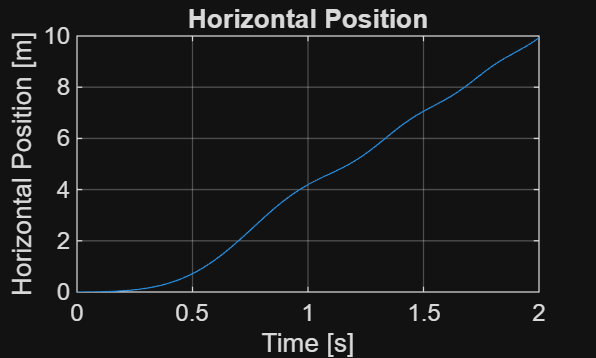

figure
plot(t,x)
xlabel('Time [s]')
ylabel('Horizontal Position [m]')
title('Horizontal Position')
grid on

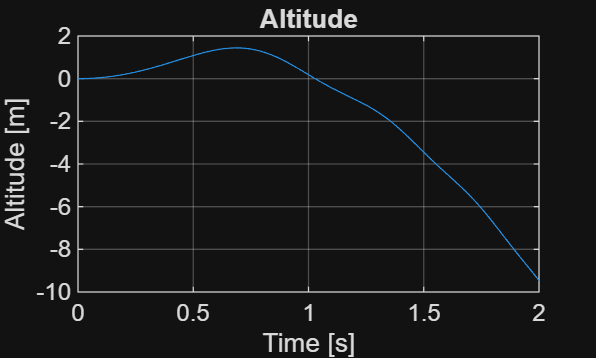


figure
plot(t,z)
xlabel('Time [s]')
ylabel('Altitude [m]')
title('Altitude')
grid on

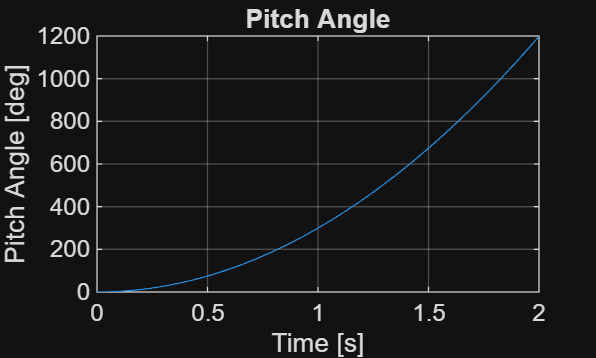


figure
plot(t,rad2deg(theta))
xlabel('Time [s]')
ylabel('Pitch Angle [deg]')
title('Pitch Angle')
grid on

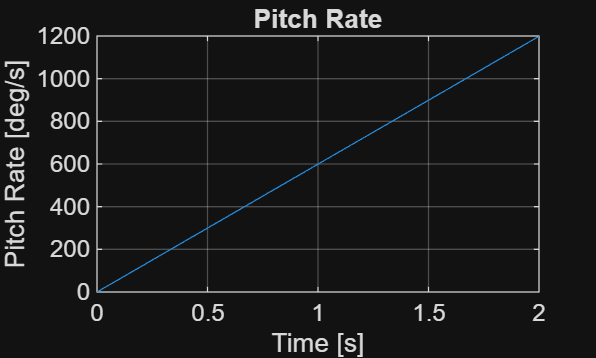


figure
plot(t,rad2deg(omega))
xlabel('Time [s]')
ylabel('Pitch Rate [deg/s]')
title('Pitch Rate')
grid on

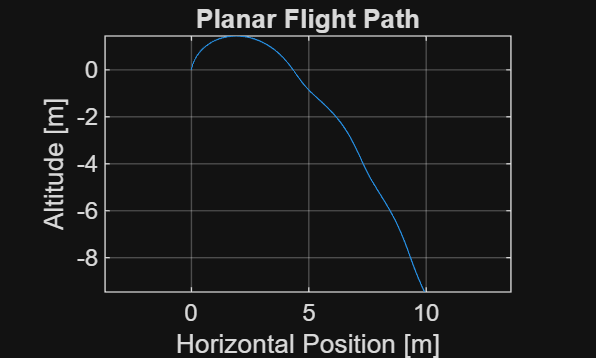


figure
plot(x,z)
xlabel('Horizontal Position [m]')
ylabel('Altitude [m]')
title('Planar Flight Path')
grid on
axis equal